fdiskret = 10E6;
tdiskret = 1/fdiskret;

tprescaler = 1;
dataSend = "101101110101010101011000111";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule, signalSNR] = GenerateSignal(dataSend, 0.8);

convTypes = ConvolutionType.empty(ConvolutionEnum.last, 0);
convTypes(ConvolutionEnum.basic) = ConvolutionType("basic", 303);
convTypes(ConvolutionEnum.negative) = ConvolutionType("negative", 303);
convTypes(ConvolutionEnum.negativeNormalized) = ConvolutionType("negative normalized", 303);
convTypes(ConvolutionEnum.extended) = ConvolutionType("exteded", 333);
convTypes(ConvolutionEnum.extendedNormalized) = ConvolutionType("extended normalized", 333);


convTypes(ConvolutionEnum.basic).convPreambule = [ones(1, 5), zeros(1, 5), ones(1, 5), zeros(1, 20), ones(1, 5), zeros(1, 5), ones(1, 5)];
convTypes(ConvolutionEnum.negative).convPreambule = [ones(1, 5), -ones(1, 5), ones(1, 5), -ones(1, 20), ones(1, 5), -ones(1, 5), ones(1, 5)];
noramlizedCoef = -20/30;
convTypes(ConvolutionEnum.negativeNormalized).convPreambule = [ones(1, 5), noramlizedCoef*ones(1, 5), ones(1, 5), noramlizedCoef*ones(1, 20), ones(1, 5), noramlizedCoef*ones(1, 5), ones(1, 5)];
convTypes(ConvolutionEnum.extended).convPreambule =  [ones(1, 5), -ones(1, 5), ones(1, 5), -ones(1, 20), ones(1, 5), -ones(1, 5), ones(1, 5), -ones(1, 30)];
extendedNormalizedCoef = -20/60;
convTypes(ConvolutionEnum.extendedNormalized).convPreambule =  [ones(1, 5), extendedNormalizedCoef*ones(1, 5), ones(1, 5), extendedNormalizedCoef*ones(1, 20), ones(1, 5), extendedNormalizedCoef*ones(1, 5), ones(1, 5), extendedNormalizedCoef*ones(1, 30)];

%Print the sum of preambule
figure; 
hold on
for i = 1:uint32(ConvolutionEnum.last)
    plot(convTypes(i).convPreambule, 'DisplayName', convTypes(i).name)
    fprintf("Sum of %s is %d\n", convTypes(i).name, sum(convTypes(i).convPreambule));
end

Sum of basic is 20
Sum of negative is -10
Sum of negative normalized is 2.553513e-15
Sum of exteded is -40
Sum of extended normalized is 1.776357e-15


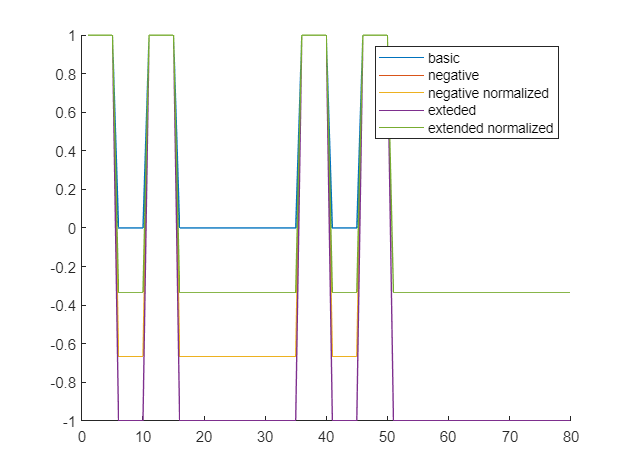

legend
hold off

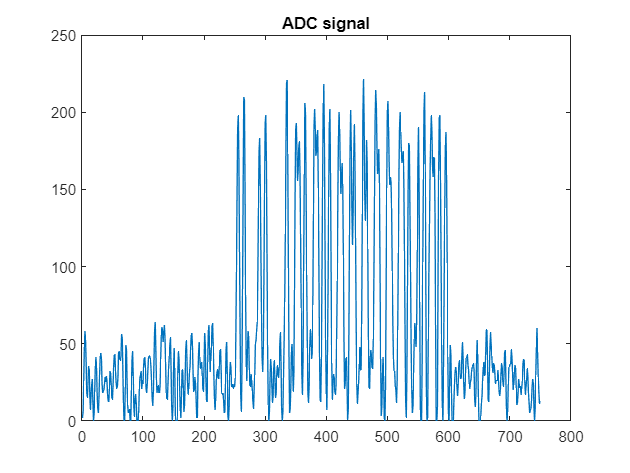

plot(ADCsignal)
title("ADC signal")

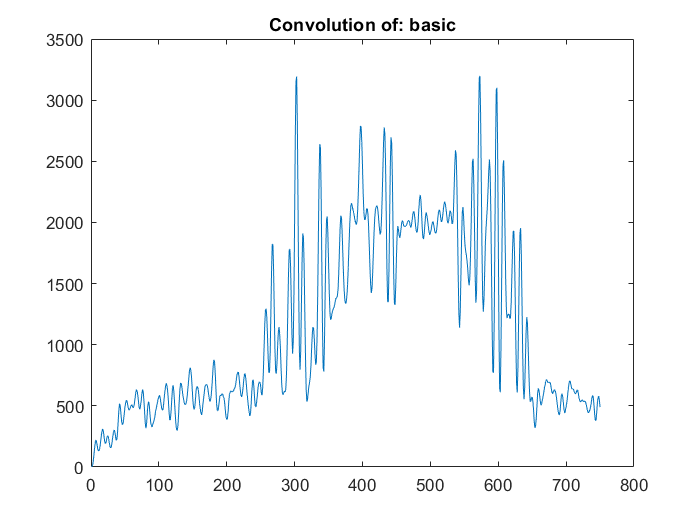

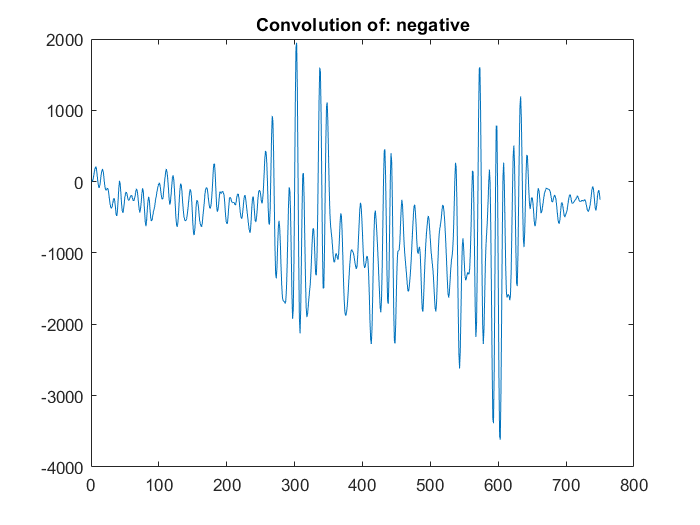

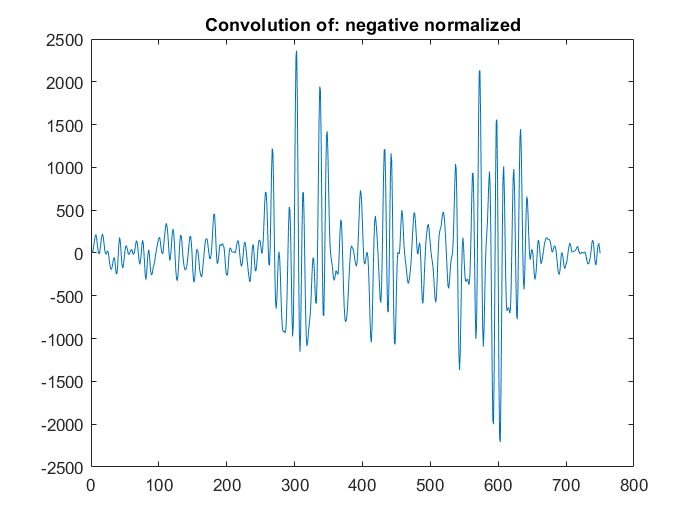

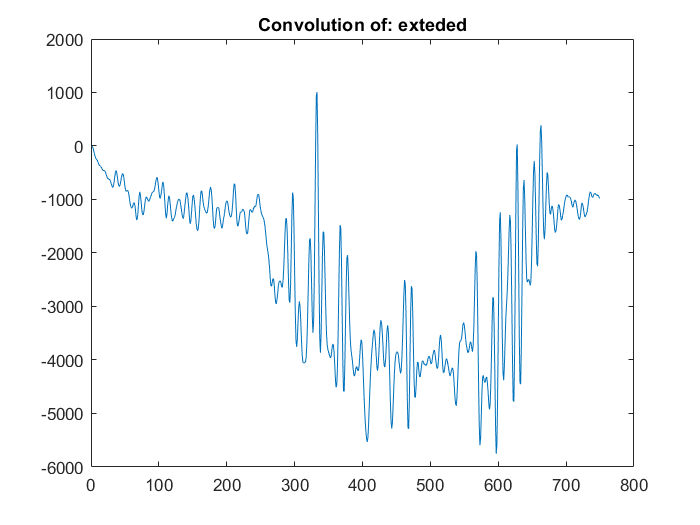

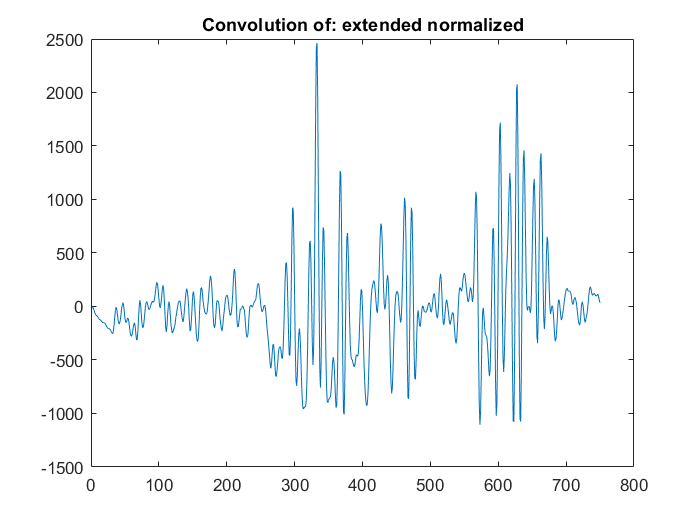

%Plot convolutions
allConvolutions = zeros(ConvolutionEnum.last, length(ADCsignal));
for i = 1:uint32(ConvolutionEnum.last)
    allConvolutions(i, :) = GenerateConv(ADCsignal, convTypes(i).convPreambule);
    figure
    plot(allConvolutions(i, :))
    title(sprintf("Convolution of: %s", convTypes(i).name))
end

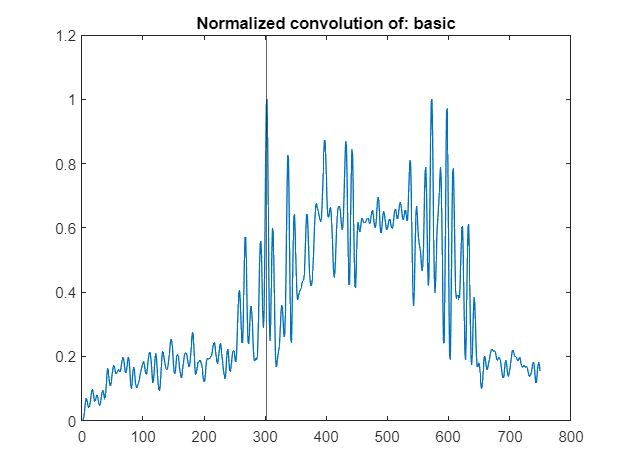

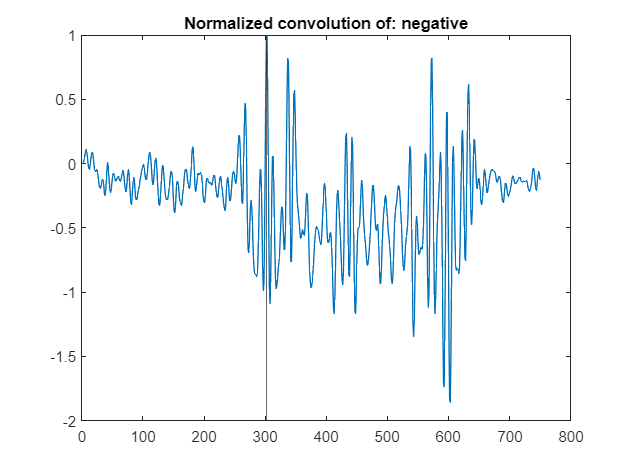

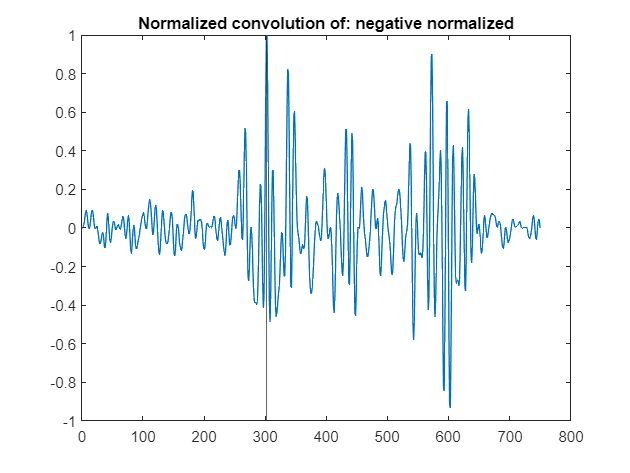

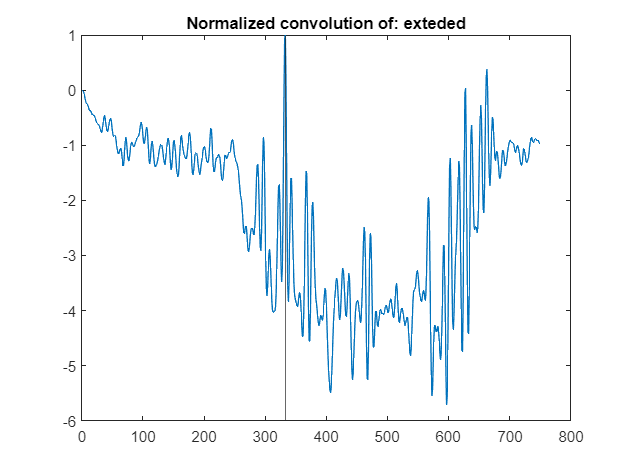

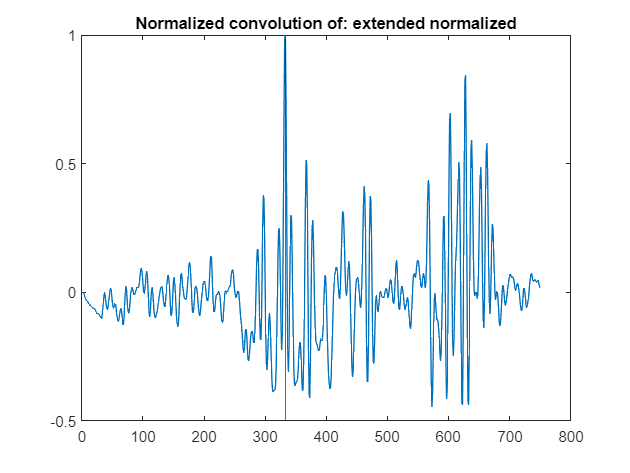

%Plot normalized convolutions
allConvolutionsNormalized = zeros(ConvolutionEnum.last, length(ADCsignal));
for i = 1:uint32(ConvolutionEnum.last)
    allConvolutionsNormalized(i, :) = allConvolutions(i, :) / allConvolutions(i, convTypes(i).expectedMaximum);
    figure
    plot(allConvolutionsNormalized(i, :))
    xline(convTypes(i).expectedMaximum)
    title(sprintf("Normalized convolution of: %s", convTypes(i).name))
end

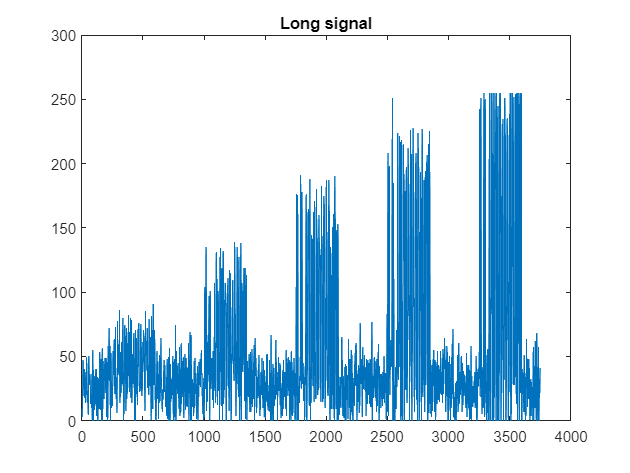

minAmplitude = 0.2;
maxAmplitude = 1.1;
stepCount = 5;

dataSend = "101101110101010101011000111";
singleSigLength = 750;
ADCsignalLong = zeros(1, stepCount*singleSigLength);
idealSignalLong = zeros(1, stepCount*singleSigLength);
for generuojama_amplitude_index = 1:stepCount
    generatedAmplitude = minAmplitude + (maxAmplitude - minAmplitude)/(stepCount-1) * (generuojama_amplitude_index-1);
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generatedAmplitude);
    copyIndexStart = singleSigLength*(generuojama_amplitude_index-1)+1;
    copyIndexLast = singleSigLength*(generuojama_amplitude_index);
    ADCsignalLong(copyIndexStart:copyIndexLast) = ADCsignal;
    idealSignalLong(copyIndexStart:copyIndexLast) = idealSignal(1:10:length(idealSignal));
end
plot(ADCsignalLong)
title("Long signal")

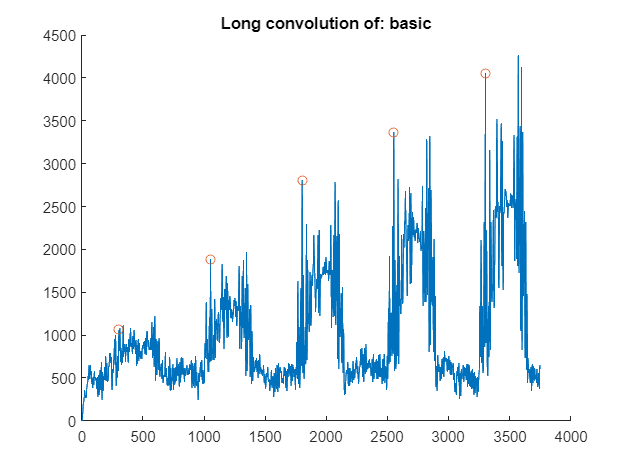

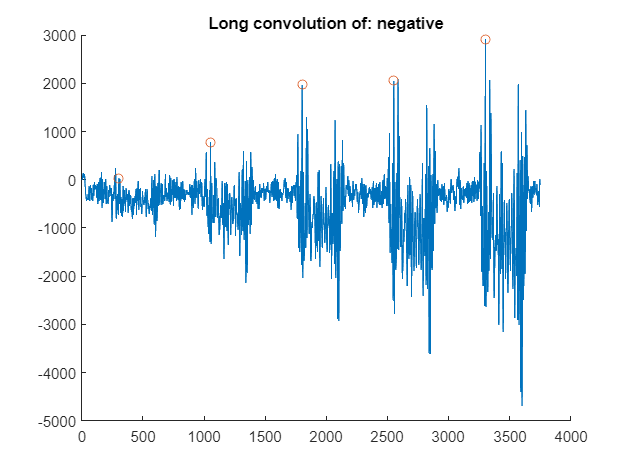

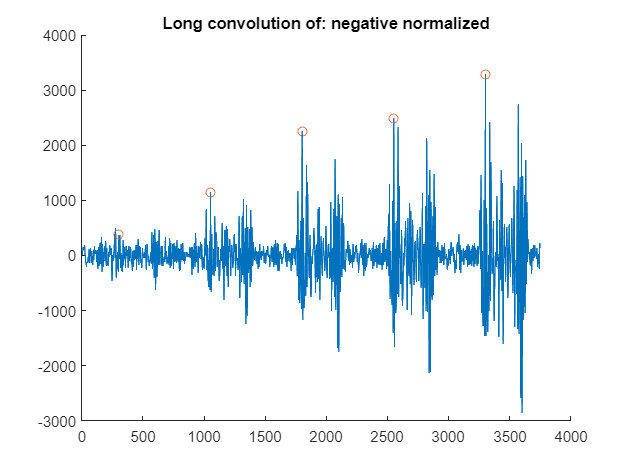

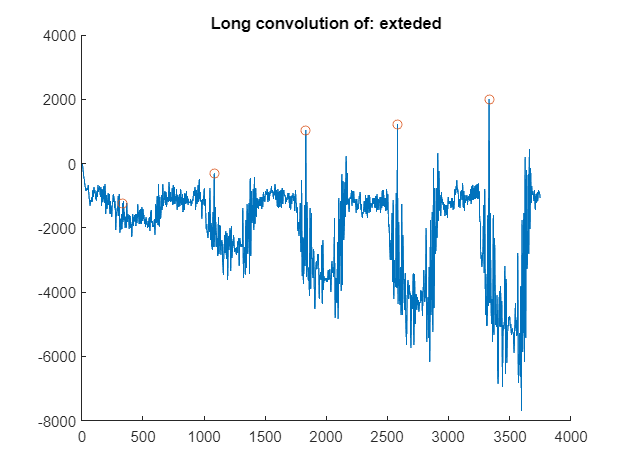

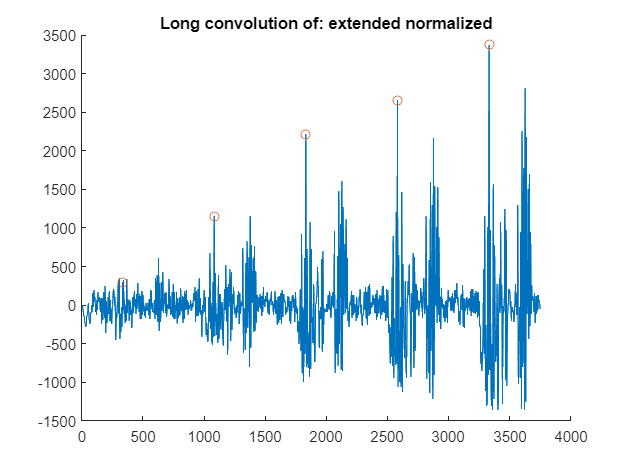

%Plot long convolutions
allLongConvolutions = zeros(ConvolutionEnum.last, length(ADCsignalLong));
for i = 1:uint32(ConvolutionEnum.last)
    allLongConvolutions(i, :) = GenerateConv(ADCsignalLong, convTypes(i).convPreambule);
    targetPointsX = zeros(1, stepCount);
    targetPointsY = zeros(1, stepCount);
    for ii = 1:stepCount
        targetPointsX(ii) = convTypes(i).expectedMaximum + length(ADCsignal) * (ii-1);
        targetPointsY(ii) = allLongConvolutions(i, targetPointsX(ii));
    end
    figure
    hold on
    plot(allLongConvolutions(i, :))
    scatter(targetPointsX, targetPointsY)
    hold off
    title(sprintf("Long convolution of: %s", convTypes(i).name))
end